# Lab 3 ESD2 - Oran Betz

Corke Toolbox:

+X: towards right side of camera

+Y: towards ground

+Z: Radially away from camera [optical axis]

Image size is 752 x 480 pixels

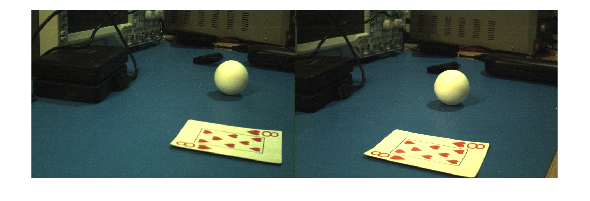

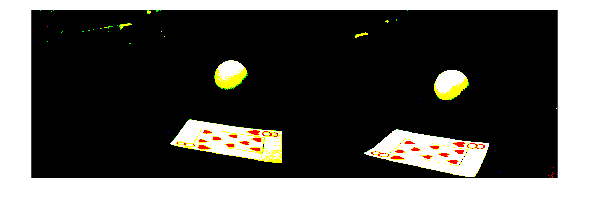

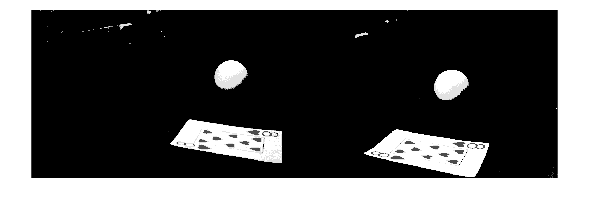

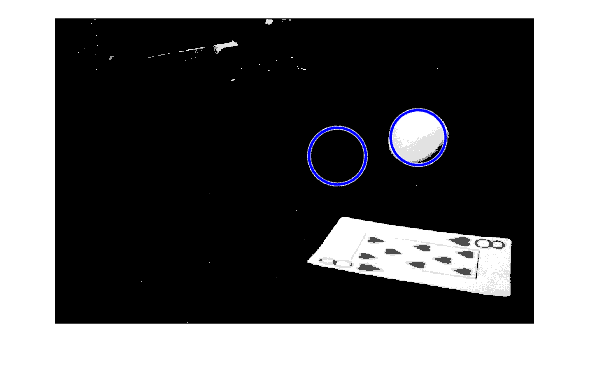

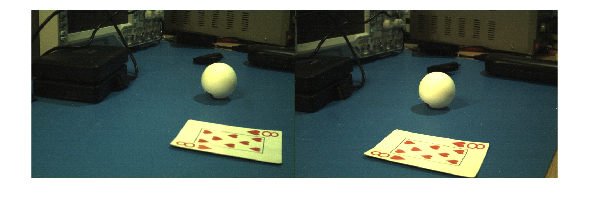

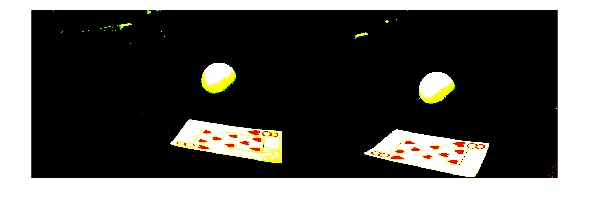

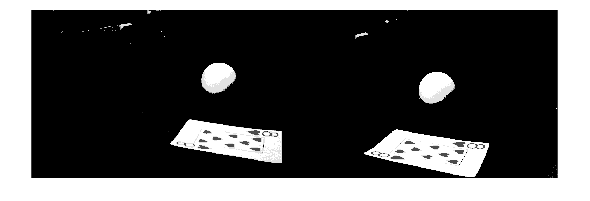

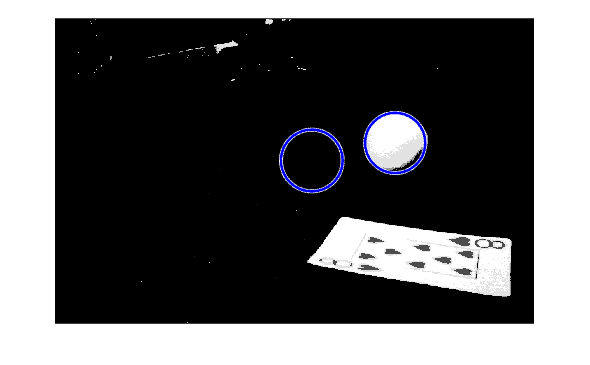

% Import Left Images
leftImageArray = ["left5.jpg","left6.jpg","left7.jpg","left8.jpg","left9.jpg"];

% Import Right Images
rightImageArray = ["right5.jpg","right6.jpg","right7.jpg","right8.jpg","right9.jpg"];

for c = 1:5

% Read Both Images 
leftImage = imread(leftImageArray(c));
rightImage = imread(rightImageArray(c));

% Show Default Image with Left and Right Camera
figure
imshowpair(leftImage,rightImage,'montage')

% Normalize Image with Left and Right Camera
normalizedImageLeft = im2double(imbinarize(leftImage,graythresh(leftImage)));
normalizedImageRight = im2double(imbinarize(rightImage,graythresh(rightImage)));
figure
imshowpair(normalizedImageLeft,normalizedImageRight,'montage')

% Set the image to Grayscale with Left and Right Camera
grayscaleImageLeft = rgb2gray(normalizedImageLeft);
grayscaleImageRight = rgb2gray(normalizedImageRight);
figure
imshowpair(grayscaleImageLeft,grayscaleImageRight,'montage')


% Find Center and Radius of Left Ball
[centerLeft, radiusLeft] = imfindcircles(grayscaleImageLeft, [20 100],'ObjectPolarity','bright', "Sensitivity",0.95);
% Find Center and Radius of Right Ball
[centerRight, radiusRight] = imfindcircles(grayscaleImageRight, [20 100],'ObjectPolarity','bright', "Sensitivity",0.95);

% Add Visual Circle to Confirm viewing of the ball
figure
imshow(grayscaleImageLeft)
viscircles(centerLeft, radiusLeft,'EdgeColor','b');
viscircles(centerRight, radiusRight,'EdgeColor','b');

## Updating Position

% Assumed Camera Variables
b = 60;    % baseline [mm]
f = 6;     % focal length [mm]
ps = .006; % pixel size [mm]

% Constants
xNumPix = 752;            % total number of pixels in x direction of the sensor [px]
yNumPix = 480;            % total number of pixels in y direction of the sensor [px]
cxLeft  = xNumPix/2;      % left camera x center [px]
cxRight = xNumPix/2;      % right camera x center [px]
cyLeft  = yNumPix/2;      % left camera y center [px]
cyRight = yNumPix/2;      % right camera y center [ 
  
% Taking XY Elements from Left and Right Found Centers
xLeft = centerLeft(1);
yLeft = centerLeft(2);
xRight = centerRight(1);
yRight = centerRight(2);

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps);  % disparity [mm]
Z = (b * f)./d/1e3;                             % depth [mm]
Z = Z/1000;                                     % depth [m]
X = Z * ((xLeft-cxLeft) * ps)/f;                % left right pos [m]
Y = Z * ((yLeft-cyLeft) * ps)/f;                % up down pos [m]

% Calculated Position of Ball
%P = [X,Y,Z]

end

%zeros(grayscaleImageLeft, 0)